# Lab 8 - Polynomial Interpolation

## Given data

t = 0:8;
y = [40.12 66.78 80.17 86.71 80.77 66.78 44.41 10.51 -32.60];


## Plotting the data

plot(t, y, 'ro');
hold on;


## Calculating best fit line

coefficients = polyfit(t, y, 1);
slope = coefficients(1);
intercept = coefficients(2);


## Plotting the best fit line

fit_line = polyval(coefficients, t);
plot(t, fit_line, 'b-');
xlabel('t');
ylabel('y');
title('Best Fit Line');


## Finding the value of y when t = 4.5 and t = 8.5

y_t4_5 = polyval(coefficients, 4.5);
y_t8_5 = polyval(coefficients, 8.5);


## Displaying results

fprintf('1. Slope: %.4f\n   Intercept: %.4f\n', slope, intercept);

1. Slope: -9.1857
   Intercept: 86.0371


fprintf('2. Value of y when t = 4.5: %.4f\n   Value of y when t = 8.5: %.4f\n', y_t4_5, y_t8_5);

2. Value of y when t = 4.5: 44.7016
   Value of y when t = 8.5: 7.9589


## Using interp1 for comparison

y_interp_t4_5 = interp1(t, y, 4.5);
y_interp_t8_5 = interp1(t, y, 8.5);

fprintf('3. Value of y using interp1 for t = 4.5: %.4f\n   Value of y using interp1 for t = 8.5: %.4f\n', y_interp_t4_5, y_interp_t8_5);

3. Value of y using interp1 for t = 4.5: 73.7750
   Value of y using interp1 for t = 8.5: NaN


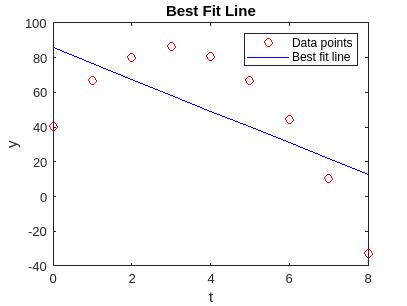


legend('Data points', 'Best fit line');